%==========================================================================
% Author:    Naghmeh Akhavan, PhD (University of Michigan)
% Script:    Fig_SingleSeq_Composition_OnsetDeciles_Human_LW2min.m (suggested)
%
% Goal:
%   Quantify how REM cycling *regimes* change across the night by comparing
%   (i) the *composition* of REM bouts (Single vs Sequential) and
%   (ii) the *mean REM bout duration* within each portion of the sleep episode.
%   The sleep episode is normalized to [0,1] within each subject, and cycles
%   are binned by the fractional time of REM onset.
%
% Inputs:
%   - Combined_BigResultTable.mat        : cycle-level summaries (NREM, IREM, REMpre, ...)
%   - Combined_BigStageDetailsTable.mat  : stage-level blocks (Stage, Duration, cycle IDs)
%
% Long-wake filtering (cycle-level DROP):
%   Drop a REM cycle if StageDetails contains ANY single contiguous Wake block
%   (Stage == WAKE_CODE, typically 5) with Duration ≥ WAKE_BREAK_MIN minutes.
%
% Per-cycle classification (GMM on log NREM):
%   1) Convert NREM seconds to minutes:  NREM_min = NREM/60
%   2) Fit a 2-component Gaussian mixture to z = log(NREM_min) (toolbox-free EM)
%   3) Identify the "small-NREM" component as the component with smaller mu
%   4) Compute posterior probability of "small-NREM" for each cycle:
%          postSmall = p(small | z)
%   5) Label:
%          Sequential  if postSmall ≥ 0.5
%          Single      otherwise
%   Only cycles with valid NREM_min are classified/used.
%
% Binning by REM onset (within-subject normalization):
%   - Define cycle duration for the "night clock" as: CycleDur_min = IREM_min + REMpre_min
%   - Compute REM onset time (minutes since start): onsetMin = cumulative cycle start + IREM_min
%   - Normalize: REM_onsetFrac = onsetMin / sum(CycleDur_min)  ∈ [0,1]
%   - Discretize REM_onsetFrac into 10 equal bins (deciles).
%
% Outputs (POOLED across subjects; classified cycles only):
%   Left panel (composition):
%     - For each onset decile: fraction Single and fraction Sequential among cycles in that bin
%     - Error bars: binomial SE, sqrt(p(1-p)/n) where n = total classified cycles in bin
%
%   Right panel (duration):
%     - For each onset decile: mean REM bout duration (REMpre, minutes) for Single vs Sequential
%     - Error bars: SEM = SD/sqrt(n) computed within each bin & class
%
% Notes:
%   - Uses custom EM for GMM (no toolboxes), but current fit_gmm_1d uses MATLAB
%     quantile() for clipping/initialization; replace with your quantile_nontb if needed.
%   - IREM is reconstructed as NREM + Wake + Movement if missing.
%   - Pooling is cycle-level (not subject-averaged); bins reflect total cycle counts.
%
% Last updated: 2026-01-16
%==========================================================================

clear; clc;


## Paths & constants

combinedFolder = 'C:\Users\naghm\OneDrive\Desktop\REM_IMPORTANT\combined_out';
matRes = fullfile(combinedFolder, 'Combined_BigResultTable.mat');        % per-cycle summaries
matStg = fullfile(combinedFolder, 'Combined_BigStageDetailsTable.mat');  % per-stage blocks

assert(isfile(matRes), 'Missing %s', matRes);
assert(isfile(matStg), 'Missing %s', matStg);

% Long-wake rule (DROP any cycle that has a single Wake block >= this)
WAKE_BREAK_MIN  = 2;                      % minutes
WAKE_BREAK_SEC  = WAKE_BREAK_MIN*60;      % seconds

% Binning along the sleep episode (0→1). 10% bins = 10 bins:
binEdges = linspace(0,1,11);
binMids  = 100 * (binEdges(1:end-1) + binEdges(2:end))/2;   % 5,15,...,95
nBins    = numel(binEdges)-1;

SAVE_FIG = false;
outPng   = fullfile(combinedFolder,'tables_out', ...
            sprintf('Fig6_SingleSeq_POOLED_FRACTION_and_DURATION_ONSET_LW%gmin_ERR.png', WAKE_BREAK_MIN));


## Load tables

S1 = load(matRes);
assert(isfield(S1,'Combined_BigResultTable'), 'Result MAT lacks Combined_BigResultTable.');
R  = S1.Combined_BigResultTable;

S2 = load(matStg);
assert(isfield(S2,'Combined_BigStageDetailsTable'), 'Stage MAT lacks Combined_BigStageDetailsTable.');
D  = S2.Combined_BigStageDetailsTable;

% Normalize types
R.Subject_Index   = string(R.Subject_Index);
R.REM_Cycle_Index = string(R.REM_Cycle_Index);

% Stage details: require at least Stage & Duration & REM_Cycle_Index
needD = ["Stage","Duration","REM_Cycle_Index"];
for v = needD
    assert(ismember(v, string(D.Properties.VariableNames)), 'Stage table missing "%s".', v);
end
D.Stage           = double(D.Stage);
D.Duration        = double(D.Duration);
D.REM_Cycle_Index = string(D.REM_Cycle_Index);

% Results: ensure needed numeric columns; reconstruct IREM if needed
needR = ["NREM","REMpre","Wake","Movement","IREM"];
for v = needR
    if ~ismember(v, string(R.Properties.VariableNames)), R.(v) = NaN(height(R),1); end
    R.(v) = double(R.(v));
end
if (all(isnan(R.IREM)) || ~ismember("IREM", string(R.Properties.VariableNames))) ...
   && all(ismember(["NREM","Wake","Movement"], string(R.Properties.VariableNames)))
    R.IREM = R.NREM + R.Wake + R.Movement;
end


## Long-wake DROP

[Gd, keys] = findgroups(D.REM_Cycle_Index);
hasLongWake = false(numel(keys),1);

WAKE_CODE = 5; 

for gi = 1:numel(keys)
    rows  = find(Gd==gi);
    st    = D.Stage(rows);
    dur   = D.Duration(rows);
    if any(st==WAKE_CODE & isfinite(dur) & dur >= WAKE_BREAK_SEC)
        hasLongWake(gi) = true;
    end
end

DropTab = table(keys, hasLongWake, 'VariableNames',{'REM_Cycle_Index','HasLongWake'});
R = outerjoin(R, DropTab, 'Keys','REM_Cycle_Index', 'MergeKeys',true, 'Type','left');

if ~ismember("HasLongWake", string(R.Properties.VariableNames))
    R.HasLongWake = false(height(R),1);
else
    R.HasLongWake = logical(fillmissing(double(R.HasLongWake), 'constant', 0));
end

dropMask = (R.HasLongWake==1);
dropped  = sum(dropMask);
Rkeep    = R(~dropMask, :);
fprintf('Long-wake DROP: Wake >= %d min — Dropped %d cycles; Kept %d.\n', ...
        WAKE_BREAK_MIN, dropped, height(Rkeep));

Long-wake DROP: Wake >= 2 min — Dropped 1028 cycles; Kept 3994.


## Classify Single vs Sequential

N_min  = Rkeep.NREM/60;
validN = isfinite(N_min) & (N_min > 0);
z      = log(N_min(validN));
if isempty(z)
    error('No valid |N| to classify after long-wake filtering.');
end

[w,mu,sd] = fit_gmm_1d(z, 2, struct( ...
    'nStarts',30,'maxIter',200,'tol',1e-6,'trimFrac',0.01, ...
    'sdMin',0.08,'sdMax',3.0,'clipQuantiles',[0.5 99.5]));

zU    = log(Rkeep.NREM/60);
maskU = isfinite(zU) & (zU>0);

[~, idxSmall] = min(mu); [~, idxLarge] = max(mu);
pS = w(idxSmall) * (1./(sd(idxSmall)*sqrt(2*pi))) .* exp(-0.5*((zU-mu(idxSmall))./sd(idxSmall)).^2);
pL = w(idxLarge) * (1./(sd(idxLarge)*sqrt(2*pi))) .* exp(-0.5*((zU-mu(idxLarge))./sd(idxLarge)).^2);
postSmall = pS ./ (pS + pL + eps);

isSequential = false(height(Rkeep),1);
isSequential(maskU) = postSmall(maskU) >= 0.5;
isSingle = maskU & ~isSequential;


## REM onset fraction per recording

IREM_min   = Rkeep.IREM/60;
REMpre_min = Rkeep.REMpre/60;

CycleDur_min = IREM_min + REMpre_min;
rec          = Rkeep.Subject_Index;

REM_onsetFrac = NaN(height(Rkeep),1);
[G, recNames] = findgroups(rec);

for gi = 1:numel(recNames)
    idx = find(G==gi);

    d = CycleDur_min(idx);
    I = IREM_min(idx);

    d(~isfinite(d) | d<0) = 0;
    I(~isfinite(I) | I<0) = 0;

    total = sum(d);
    if total <= 0, continue; end

    cumStart = [0; cumsum(d(1:end-1))];
    onsetMin = cumStart + I;

    REM_onsetFrac(idx) = onsetMin / total;
end

binID = discretize(REM_onsetFrac, binEdges);


## POOLED aggregation across subjects

okBin = isfinite(binID) & ~isnan(binID) & binID>=1 & binID<=nBins;
okCls = maskU;
ok    = okBin & okCls;

bAll  = double(binID(ok));
REMm  = REMpre_min(ok);

% Total bouts per bin (all classified cycles)
cTot = safe_accum_count(bAll, nBins);

% Single/Sequential counts
cS   = safe_accum_count(bAll(isSingle(ok)),     nBins);
cQ   = safe_accum_count(bAll(isSequential(ok)), nBins);

% Fractions
fracSingle = NaN(1,nBins);
fracSeq    = NaN(1,nBins);
nz = cTot > 0;
fracSingle(nz) = (cS(nz) ./ cTot(nz))';
fracSeq(nz)    = (cQ(nz) ./ cTot(nz))';

% ERROR BARS for fractions (binomial SE)
seFracSingle = NaN(1,nBins);
seFracSeq    = NaN(1,nBins);
seFracSingle(nz) = sqrt( fracSingle(nz) .* (1-fracSingle(nz)) ./ max(cTot(nz)',1) );
seFracSeq(nz)    = sqrt( fracSeq(nz)    .* (1-fracSeq(nz))    ./ max(cTot(nz)',1) );

% Mean bout duration (pooled mean) + SEM
durSingle   = safe_accum_mean(bAll(isSingle(ok)),     REMm(isSingle(ok)),     nBins)';
durSeq      = safe_accum_mean(bAll(isSequential(ok)), REMm(isSequential(ok)), nBins)';

sdSingle    = safe_accum_std (bAll(isSingle(ok)),     REMm(isSingle(ok)),     nBins)';
sdSeq       = safe_accum_std (bAll(isSequential(ok)), REMm(isSequential(ok)), nBins)';

nSingle     = safe_accum_count(bAll(isSingle(ok)),     nBins)';
nSeq        = safe_accum_count(bAll(isSequential(ok)), nBins)';

semSingle   = NaN(1,nBins);
semSeq      = NaN(1,nBins);
semSingle(nSingle>0) = sdSingle(nSingle>0) ./ sqrt(nSingle(nSingle>0));
semSeq(nSeq>0)       = sdSeq(nSeq>0)       ./ sqrt(nSeq(nSeq>0));

% Subject count for display
nSubj = numel(recNames);
fprintf('Pooled analysis over N=%d subjects (classified cycles only).\n', nSubj);

Pooled analysis over N=554 subjects (classified cycles only).


## Plots

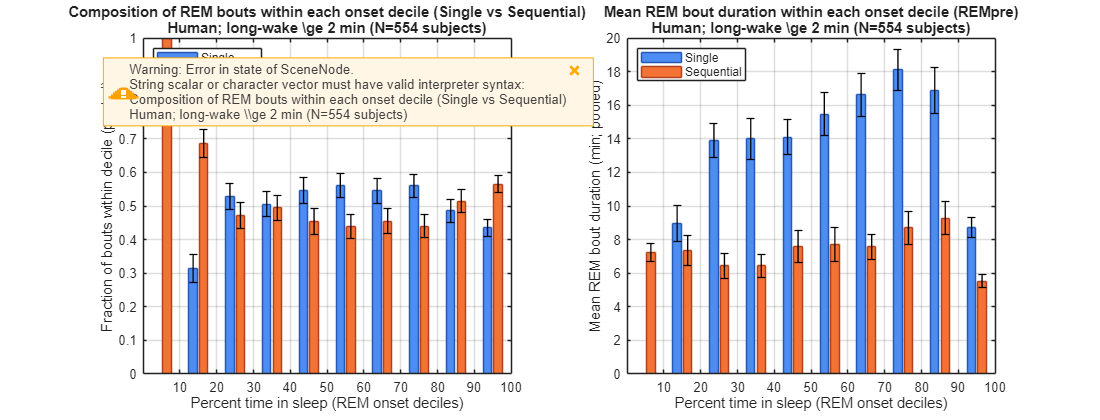

figure('Color','w','Position',[100 100 1100 420]);

% Left: pooled fraction + error bars
subplot(1,2,1);
B1 = bar(binMids, [fracSingle(:) fracSeq(:)], 'grouped'); hold on;
B1(1).FaceColor = [0.30 0.55 0.95];  B1(1).EdgeColor = [0.15 0.35 0.70];
B1(2).FaceColor = [0.95 0.45 0.20];  B1(2).EdgeColor = [0.70 0.25 0.12];

% Errorbar x-positions aligned to grouped bars
xS = B1(1).XEndPoints;
xQ = B1(2).XEndPoints;
errorbar(xS, fracSingle, seFracSingle, 'k', 'linestyle','none', 'LineWidth',1);
errorbar(xQ, fracSeq,    seFracSeq,    'k', 'linestyle','none', 'LineWidth',1);

xlabel('Percent time in sleep (REM onset deciles)');
ylabel('Fraction of bouts within decile (pooled)');
title({'Composition of REM bouts within each onset decile (Single vs Sequential)', ...
       sprintf('Human; long-wake \\ge %d min (N=%d subjects)', WAKE_BREAK_MIN, nSubj)});
legend({'Single','Sequential'}, 'Location','northwest'); grid on; box on;
xticks(10:10:100);
xlim([0 100]);
ylim([0 1]);

% Right: pooled mean duration + SEM error bars
subplot(1,2,2);
B2 = bar(binMids, [durSingle(:) durSeq(:)], 'grouped'); hold on;
B2(1).FaceColor = [0.30 0.55 0.95];  B2(1).EdgeColor = [0.15 0.35 0.70];
B2(2).FaceColor = [0.95 0.45 0.20];  B2(2).EdgeColor = [0.70 0.25 0.12];

xS2 = B2(1).XEndPoints;
xQ2 = B2(2).XEndPoints;
errorbar(xS2, durSingle, semSingle, 'k', 'linestyle','none', 'LineWidth',1);
errorbar(xQ2, durSeq,    semSeq,    'k', 'linestyle','none', 'LineWidth',1);

xlabel('Percent time in sleep (REM onset deciles)');
ylabel('Mean REM bout duration (min; pooled)');
title({'Mean REM bout duration within each onset decile (REMpre)', ...
       sprintf('Human; long-wake \\ge %d min (N=%d subjects)', WAKE_BREAK_MIN, nSubj)});
legend({'Single','Sequential'}, 'Location','northwest'); grid on; box on;
xticks(10:10:100);
xlim([0 100]);


if SAVE_FIG
    if ~isfolder(fileparts(outPng)), mkdir(fileparts(outPng)); end
    exportgraphics(gcf, outPng, 'Resolution', 300);
    fprintf('Saved: %s\n', outPng);
end


## Functions

% safe_accum_count: Counts items per bin robustly (handles empty input)
% safe_accum_mean: Computes mean value per bin
% safe_accum_std: Computes within-bin sample SD
function v = safe_accum_count(idx, nBins)
idx = idx(:);
idx = idx(isfinite(idx) & idx>=1 & idx<=nBins);
if isempty(idx)
    v = zeros(nBins,1);
else
    v = accumarray(idx, 1, [nBins,1], @sum, 0);
end
end

function v = safe_accum_mean(idx, vals, nBins)
idx  = idx(:);
vals = vals(:);
ok = isfinite(idx) & idx>=1 & idx<=nBins & isfinite(vals);
idx  = idx(ok);
vals = vals(ok);

v = NaN(nBins,1);
if isempty(idx), return; end

s = accumarray(idx, vals, [nBins,1], @sum, 0);
c = accumarray(idx, 1,    [nBins,1], @sum, 0);

nz = c>0;
v(nz) = s(nz)./c(nz);
end

function v = safe_accum_std(idx, vals, nBins)
% sample SD within each bin; NaN where <2 points
idx  = idx(:);
vals = vals(:);
ok = isfinite(idx) & idx>=1 & idx<=nBins & isfinite(vals);
idx  = idx(ok);
vals = vals(ok);

v = NaN(nBins,1);
if isempty(idx), return; end

for b = 1:nBins
    vb = vals(idx==b);
    if numel(vb) >= 2
        v(b) = std(vb, 0); % sample std
    elseif numel(vb) == 1
        v(b) = 0;          % define SD=0 for single observation
    end
end
end


## GMM function

% fit_gmm_1d
%em_core
function [w, mu, sd, info] = fit_gmm_1d(x, K, opts)
x = x(:); x = x(isfinite(x));
if nargin<3, opts = struct; end
g = @(f,def) (isfield(opts,f)&&~isempty(opts.(f))).*opts.(f) + (~isfield(opts,f)||isempty(opts.(f))).*def;
nStarts  = g('nStarts',15);
maxIter  = g('maxIter',200);
tol      = g('tol',1e-6);
trimFrac = g('trimFrac',0.01);
sdMin    = g('sdMin',0.08);
sdMax    = g('sdMax',3.0);
cq       = g('clipQuantiles',[0.5 99.5]);

qlo = quantile(x, cq(1)/100); qhi = quantile(x, cq(2)/100);
x   = x(x>=qlo & x<=qhi);
log2pi = log(2*pi);

bestLL = -inf; best = [];
for s = 1:nStarts
    mu0 = linspace(quantile(x,0.2), quantile(x,0.8), K) + 0.05*randn(1,K);
    sd0 = max(sdMin, 0.3*std(x))*ones(1,K);
    w0  = ones(1,K)/K;
    [w1, mu1, sd1, LL] = em_core(x, w0, mu0, sd0, maxIter, tol, trimFrac, sdMin, sdMax, log2pi);
    if LL(end) > bestLL, bestLL = LL(end); best = {w1,mu1,sd1,LL}; end
end
[w, mu, sd, LL] = best{:}; 
info = struct('loglik',LL,'nStarts',nStarts,'n',numel(x)); 
end

function [w, mu, sd, LL] = em_core(x, w, mu, sd, maxIter, tol, trimFrac, sdMin, sdMax, log2pi)
n = numel(x); K = numel(w); LL = zeros(maxIter,1); trimN = floor(trimFrac*n);
for it = 1:maxIter
    logp = zeros(n,K);
    for k=1:K
        v = sd(k)^2;
        logp(:,k) = -0.5*log2pi - 0.5*log(v) - (x-mu(k)).^2/(2*v) + log(max(w(k),eps));
    end
    m = max(logp,[],2); p = exp(logp - m); s = sum(p,2);
    gamma = p ./ max(s,eps);

    if trimN>0
        [~,idx] = sort(s, 'ascend'); keep = true(n,1); keep(idx(1:trimN)) = false;
    else
        keep = true(n,1);
    end

    Nk = sum(gamma(keep,:), 1);
    w  = Nk ./ max(sum(Nk), eps);
    for k=1:K
        mu(k) = sum(gamma(keep,k).*x(keep)) / max(Nk(k), eps);
        v     = sum(gamma(keep,k).*(x(keep)-mu(k)).^2) / max(Nk(k), eps);
        sd(k) = sqrt(max(sdMin^2, min(v, sdMax^2)));
    end

    xk = x(keep);
    logp = zeros(sum(keep),K);
    for k=1:K
        v = sd(k)^2;
        logp(:,k) = -0.5*log2pi - 0.5*log(v) - (xk-mu(k)).^2/(2*v) + log(max(w(k),eps));
    end
    m = max(logp,[],2);
    LL(it) = sum(m + log(sum(exp(logp - m),2)));
    if it>1 && abs(LL(it)-LL(it-1)) < tol*max(1,abs(LL(it-1))), LL = LL(1:it); break; end
end
LL = LL(1:it);
end
